# Glider V-n Daigram

clear all; close all; clc;


## set defaults to latex


% Pre-script
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'tex');
end

## Define Values For Maniver Diagram

% for program development we will use the DG-1000T Data

W_MGTO = 7354.9875; % Maximum Gross Takeoff Weight (N)
W_gross = W_MGTO; % Gorss Wegiht (N)
W_oe = W_gross; % operating empty weight (N)
category = "Aerobatic"; % Max g limit catregory
S = 17.53; % Wing Area (m^2)
A = 22.82; % aspect ratio (~)
Lambda_LE = deg2rad(-2); % leading edge sweep angle (radians)
lambda = .5/2.1; % taper ratio (~)
M = 0; % Mach number (~) (for incompressible M = 0)
alpha_stall = deg2rad(15); % stall angle (radians)
alt = 0; % altitude (m)
C_D_0 = .00829; % minimum drag coeefficient (Backed out from L/D max)

% is is a GUESSED value
e = .9% oswald efficiency factor (GUESS)

e = 0.9000


% % Here is the Data for our Aircraft
W_MGTO = 700*9.81; % Maximum Gross Takeoff Weight (N)
W_gross = W_MGTO; % Gorss Wegiht (N)
W_oe = W_gross; % operating empty weight (N)
category = "Aerobatic"; % Max g limit catregory
A = 28; % aspect ratio (~)
b = 20; % wing span (m)
S = b^2/A; % Wing Area (m^2)


%category = "Utility"; % Max g limit catregory

% for now i am assuming sea level -clarify this with Dr. Barrett
[~, ~, ~, rho] = atmosisa(0); % atmospheric density (kg/m^3)


% note: was unable to find data for the DG-1000 airfoild so used the
% ASW-22's airfoild which is a DU84-132v3 - then assuemd C_l_alpha is flat
% plate is 2 pi
C_l_alpha = 2*pi % lift curve slope of flat plate

C_l_alpha = 6.2832

C_L_max_neg = -.8; % in absence of better information this is acceptable 

% plotting parameters
V_max_plot = 110; % maximum velocity to plot (m/s)
n_plot_points = 100; % number of points to plot (~)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% gust diagram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

W_TO = W_MGTO;
c_bar  = b/A; % c_bar (m) DG 1000T
g = 9.81; % acceleration due to gravity in (m/s)

## Maneuver Diagram

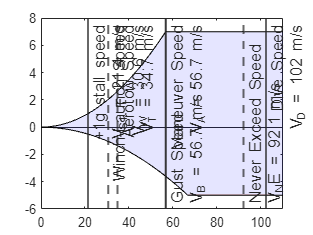

% Determine Aircraft Parameters
%find C_L_max
C_L_alpha = polhamus(C_l_alpha, A, Lambda_LE, lambda, M);
C_L_max = C_L_alpha .* C_l_alpha ./ (2*pi) .* alpha_stall;

%Velocities for plotting
V = linspace(0, V_max_plot, n_plot_points);

% Compute Valaues of the function
[n_lim_pos, n_lim_neg, V_S1, V_A, V_B, V_D, V_T, V_W, V_NE] = LoadFactor_Manuver_CS22(W_gross, W_oe, W_TO, category, S, C_L_max, V, alt, C_D_0, A, e, C_L_max_neg);


% plot upper and lower manuver limits
figure;
plot(V, n_lim_pos, 'HandleVisibility','off'); hold on
plot(V, n_lim_neg, 'HandleVisibility','off');

area(V, n_lim_pos, "FaceAlpha",.10,"FaceColor",[0,0,1], 'DisplayName', "Manuver Envelope");
area(V, n_lim_neg, "FaceAlpha",.10,"FaceColor",[0,0,1], 'HandleVisibility','off');

%plot important V speeds
xline(V_A, "-", {"Maneuver Speed", sprintf("V_A = %.3g m/s",V_A)}, 'DisplayName', "Mandatory Design Speed", "FontSize",12,LineWidth=1.5); % plot manuver speed
xline(V_S1, "-", {"+1g stall speed", sprintf("V_{S1} = %.3g m/s",V_S1)}, 'HandleVisibility','off', "FontSize",12, LineWidth=1.5); % plot 1g stall speed
xline(V_B, "-", {"Gust Speed", sprintf("V_B = %.3g m/s",V_B)}, 'HandleVisibility','off', "FontSize",12, LabelVerticalAlignment="bottom", LineWidth=1.5); % plot cruise speed
xline(V_D, "-", {"Dive Speed", sprintf("V_D = %.3g m/s",V_D)}, 'HandleVisibility','off', "FontSize",12, LineWidth=1.5); % plot dive speed
xline(V_NE, "--", {"Never Exceed Speed", sprintf("V_NE = %.3g m/s",V_NE)}, 'HandleVisibility','off', "FontSize",12, LabelVerticalAlignment="bottom", LineWidth=1.5); % Never exceed speed

xline(V_T, "--", {"Aerotow Speed", sprintf("V_T = %.3g m/s",V_T)}, 'DisplayName', "Optional Design Speed", "FontSize",12, LineWidth=1.5); % plot aerotow speed
xline(V_W, "--", {"Winch-Launch Speed", sprintf("V_W = %.3g m/s",V_W)}, 'HandleVisibility','off', "FontSize",12, LineWidth=1.5); % plot winch-launch speed

## Gust Diagram

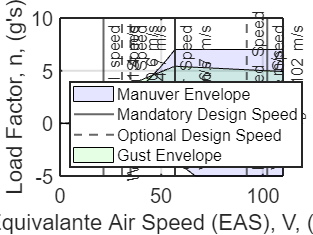

% compute the bounds of the gust envelope
[n_lim_gust_pos, n_lim_gust_neg] = LoadFactor_Gust_CS22(W_gross, S, c_bar, C_L_alpha, V, alt, V_S1, V_B, V_D);

% plot the gust envelope
plot(V, n_lim_gust_pos, 'HandleVisibility','off');
plot(V, n_lim_gust_neg, 'HandleVisibility','off');

area(V, n_lim_gust_pos, "FaceAlpha",.10,"FaceColor",[0,1,0], 'DisplayName', "Gust Envelope");
area(V, n_lim_gust_neg, "FaceAlpha",.10,"FaceColor",[0,1,0], 'HandleVisibility','off');

legend show;
legend("FontSize",12);
legend("Location","southwest");
ylabel("Load Factor, n, (g's)", "Interpreter","tex", "FontSize",15);
xlabel("Equivalante Air Speed (EAS), V, (m/s)", "Interpreter","tex", "FontSize",15);
grid on;
set(gca,'LineWidth',1.5);
set(gca,'FontSize',15);